## **LAB REPORT OF  EXPERIMENT No.11**

## Ambient Vibration Testing for Modal Identification of WLE Building

### **Name : Prajakta Kapre**

### **Roll no. : 22103040**

**Procedure:**

During this exercise, two different types of sensors will be used for measuring the ambient vibrations of the WLE building: 

(i) triaxial force balance accelerometers (measures acceleration in X, Y and Z direction) 

(ii) uniaxial seismometer (measures velocity in one direction only).

 For each type of setup, vibration measurements in both the transverse and longitudinal directions will be recorded from each floor. Therefore, only one set of measurements is necessary for the triaxial accelerometers. 

On the other hand, there will be two sets of measurements for the uniaxial seismometers: 

(i) all seismometers aligned along the longitudinal direction 

(ii) all seismometers aligned along the transverse direction of the building. 

% IMPORTING  data 
vel_x_T1=lvm_import('Vel_X_T1');


lvm_import v3.1
 Importing "Vel_X_T1.lvm"

 Segment 1:

 10 Data Columns:
 | X_Value | FBA_X__FF | FBA_X__SF | FBA_X__TF | FBA_Y__FF | FBA_Y__SF | FBA_Y__TF | Vel__FF | Vel__SF | Vel__TF | 

 Importing data from Segment 1... complete (446000 data points (rows)).


 Import complete. File has one X-Column and 1 Data Segment.



vel_x_T2=lvm_import('Vel_X_T2');


lvm_import v3.1
 Importing "Vel_X_T2.lvm"

 Segment 1:

 10 Data Columns:
 | X_Value | FBA_X__FF | FBA_X__SF | FBA_X__TF | FBA_Y__FF | FBA_Y__SF | FBA_Y__TF | Vel__FF | Vel__SF | Vel__TF | 

 Importing data from Segment 1... complete (268000 data points (rows)).


 Import complete. File has one X-Column and 1 Data Segment.



vel_x_T3=lvm_import('Vel_X_T3');


lvm_import v3.1
 Importing "Vel_X_T3.lvm"

 Segment 1:

 10 Data Columns:
 | X_Value | FBA_X__FF | FBA_X__SF | FBA_X__TF | FBA_Y__FF | FBA_Y__SF | FBA_Y__TF | Vel__FF | Vel__SF | Vel__TF | 

 Importing data from Segment 1... complete (412000 data points (rows)).


 Import complete. File has one X-Column and 1 Data Segment.



vel_y_T1=lvm_import('Vel_X_T1');


lvm_import v3.1
 Importing "Vel_X_T1.lvm"

 Segment 1:

 10 Data Columns:
 | X_Value | FBA_X__FF | FBA_X__SF | FBA_X__TF | FBA_Y__FF | FBA_Y__SF | FBA_Y__TF | Vel__FF | Vel__SF | Vel__TF | 

 Importing data from Segment 1... complete (446000 data points (rows)).


 Import complete. File has one X-Column and 1 Data Segment.



vel_y_T2=lvm_import('Vel_X_T2');


lvm_import v3.1
 Importing "Vel_X_T2.lvm"

 Segment 1:

 10 Data Columns:
 | X_Value | FBA_X__FF | FBA_X__SF | FBA_X__TF | FBA_Y__FF | FBA_Y__SF | FBA_Y__TF | Vel__FF | Vel__SF | Vel__TF | 

 Importing data from Segment 1... complete (268000 data points (rows)).


 Import complete. File has one X-Column and 1 Data Segment.



vel_y_T3=lvm_import('Vel_X_T3');


lvm_import v3.1
 Importing "Vel_X_T3.lvm"

 Segment 1:

 10 Data Columns:
 | X_Value | FBA_X__FF | FBA_X__SF | FBA_X__TF | FBA_Y__FF | FBA_Y__SF | FBA_Y__TF | Vel__FF | Vel__SF | Vel__TF | 

 Importing data from Segment 1... complete (412000 data points (rows)).


 Import complete. File has one X-Column and 1 Data Segment.




v_x_T1=vel_x_T1.Segment1.data;
v_x_T2=vel_x_T2.Segment1.data;
v_x_T3=vel_x_T3.Segment1.data;
v_y_T1=vel_y_T1.Segment1.data;
v_y_T2=vel_y_T2.Segment1.data;
v_y_T3=vel_y_T3.Segment1.data;


### 1. Analysis in X-direction

% Tearing the data
% X DIRECTION


fir_acct_x = (v_x_T3(:,2));
fir_acct_x=fir_acct_x-mean(fir_acct_x(1:100));

sec_acct_x = (v_x_T3(:,3));
sec_acct_x=sec_acct_x-mean(sec_acct_x(1:100));

third_acct_x = (v_x_T3(:,4));
third_acct_x=third_acct_x-mean(third_acct_x(1:100));

fir_vel_x = (v_x_T3(:,8));
fir_vel_x=fir_vel_x-mean(fir_vel_x(1:100));

sec_vel_x = (v_x_T3(:,9));
sec_vel_x=sec_vel_x-mean(sec_vel_x(1:100));

third_vel_x = (v_x_T3(:,10));
third_vel_x=third_vel_x-mean(third_vel_x(1:100));

t = v_x_T3(:,1);


% FDD for acceleration in x-direction

T = 0.0005            % Sampling period                    

T = 5.0000e-04

fs = 1/T

fs = 2000


[p11,F11] = cpsd(fir_acct_x,fir_acct_x,[],[],[],fs); %fs is sampling frequency
[p12,F12] = cpsd(fir_acct_x,sec_acct_x,[],[],[],fs);
[p13,F13] = cpsd(fir_acct_x,third_acct_x,[],[],[],fs);
[p21,F21] = cpsd(sec_acct_x,fir_acct_x,[],[],[],fs);
[p22,F22] = cpsd(sec_acct_x,sec_acct_x,[],[],[],fs);
[p23,F23] = cpsd(sec_acct_x,third_acct_x,[],[],[],fs);
[p31,F31] = cpsd(third_acct_x,fir_acct_x,[],[],[],fs);
[p32,F32] = cpsd(third_acct_x,sec_acct_x,[],[],[],fs);
[p33,F33] = cpsd(third_acct_x,third_acct_x,[],[],[],fs);
f = F11';

for i = 1:length(f)
Sxx = [p11(i),p12(i),p13(i);p21(i),p22(i),p23(i);p31(i),p32(i),p33(i)];
[U,D,V] = svd(Sxx);
sigma1_x(i) = D(1,1);

U11(i)=U(1,1); % U1n for 1 st  mode
U21(i)=U(2,1);
U31(i)=U(3,1);


end
matrix_sigma1x_freq=[f' sigma1_x'] % to get indices of corresponding wn

matrix_sigma1yv_freq = 1.0e+03 *

         0    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0001    0.0000
    0.0001    0.0000
    0.0001    0.0000
    0.0001    0.0000
    0.0001    0.0000
    0.0001    0.0000


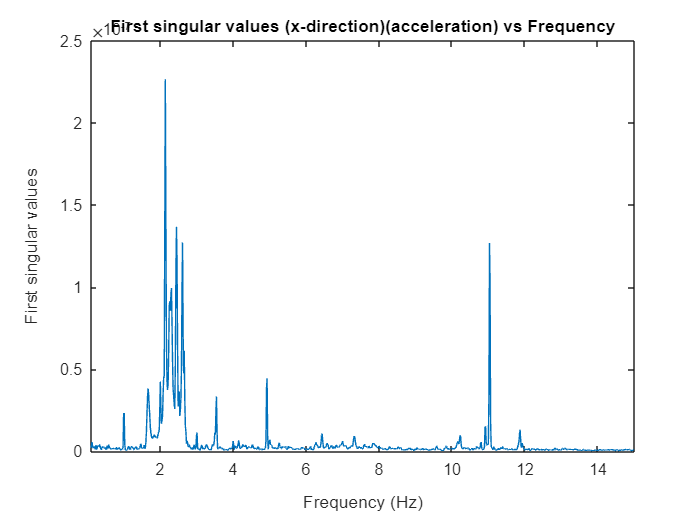

figure;plot(f',sigma1_x);
title('First singular values (x-direction)(acceleration) vs Frequency');
xlabel('Frequency (Hz)');
ylabel('First singular values');
xlim([0.1 15]);


% Finding mode shapes using acc in x-direction data
B=[U11; U21 ;U31];


phi1_acc_x=B(:,141); % 3278 is the row number for wn1=2.136Hz
phi2_acc_x=B(:,324); % 3278 is the row number for wn2=4.9285Hz
phi3_acc_x=B(:,724); % 3278 is the row number for wn3=11.032Hz

phi_acc_x=([phi1_acc_x phi2_acc_x phi3_acc_x])

phi_acc_x =   -0.1987 - 0.0000i  -0.0389 + 0.0000i  -0.6236 - 0.0000i
   0.0930 + 0.0030i  -0.2340 + 0.0990i  -0.5440 - 0.0258i
   0.9756 - 0.0120i  -0.8519 + 0.4563i  -0.5317 - 0.1784i


From First singular value plots of acceleration  in x-direction, the natural frequencies are:

- wn1_acc_x=2.14 Hz

- wn2_acc__x=4.93 Hz

- wn3_acc_x=11.03Hz

The mode shapes are shown below.

% FDD for velocity in x-direction

T = t(2)-t(1);            % Sampling period                    
fs = 1/T

fs = 200

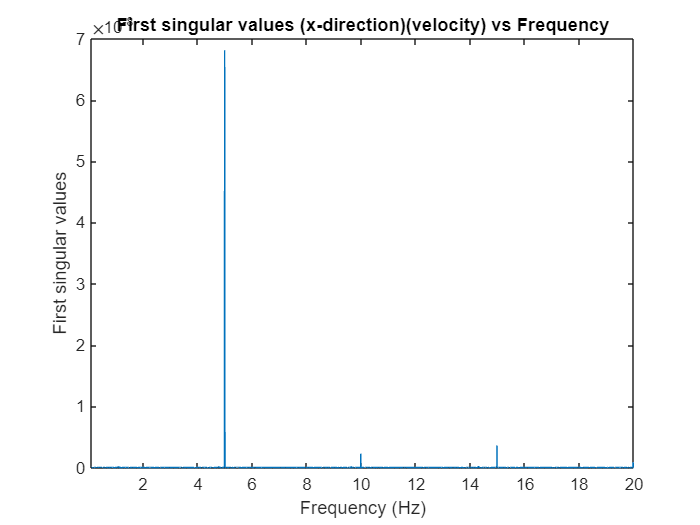


[p11,F11] = cpsd(fir_vel_x,fir_vel_x,[],[],[],fs); %fs is sampling frequency
[p12,F12] = cpsd(fir_vel_x,sec_vel_x,[],[],[],fs);
[p13,F13] = cpsd(fir_vel_x,third_vel_x,[],[],[],fs);
[p21,F21] = cpsd(sec_vel_x,fir_vel_x,[],[],[],fs);
[p22,F22] = cpsd(sec_vel_x,sec_vel_x,[],[],[],fs);
[p23,F23] = cpsd(sec_vel_x,third_vel_x,[],[],[],fs);
[p31,F31] = cpsd(third_vel_x,fir_vel_x,[],[],[],fs);
[p32,F32] = cpsd(third_vel_x,sec_vel_x,[],[],[],fs);
[p33,F33] = cpsd(third_vel_x,third_vel_x,[],[],[],fs);
f = F11';

for i = 1:length(f)
Sxx = [p11(i),p12(i),p13(i);p21(i),p22(i),p23(i);p31(i),p32(i),p33(i)];
[U,D,V] = svd(Sxx);
sigma1_x_vel(i) = D(1,1);

U11(i)=U(1,1); % U1n for 1 st  mode
U21(i)=U(2,1);
U31(i)=U(3,1);


end
matrix_sigma1v_freq=[f' sigma1_x_vel']; % to get indices of corresponding wn
figure;plot(f',sigma1_x_vel');
title('First singular values (x-direction)(velocity) vs Frequency');
xlabel('Frequency (Hz)');
ylabel('First singular values');
xlim([0.1 20]);


% Finding mode shapes using acc in x-direction data
B1=[U11; U21 ;U31];


phi1_acc_x=B1(:,292); % 292 is the row number for wn1=4.44 Hz
phi2_acc_x=B1(:,560); % 560 is the row number for wn2=8.529Hz
phi3_acc_x=B1(:,724); % 724 is the row number for wn3=11.032Hz

phi_vel_x=([phi1_acc_x phi2_acc_x phi3_acc_x])

phi_vel_x =   -0.3660 - 0.0000i  -0.4028 + 0.0000i  -0.5945 - 0.0000i
  -0.6197 - 0.0082i  -0.6376 + 0.0352i  -0.6557 - 0.0127i
  -0.6939 - 0.0222i  -0.6552 + 0.0263i  -0.4616 - 0.0582i


From First singular value plots of velocity in x-direction, the natural frequencies are:

- wn1_acc_x=4.44 Hz

- wn2_acc__x=8.53 Hz

- wn3_acc_x=11.03 Hz

### 2. Analysis in Y-direction

% Tearing the data
% Y DIRECTION


fir_acct_y = (v_y_T3(:,5));
fir_acct_y=fir_acct_y-mean(fir_acct_y(1:100));

sec_acct_y = (v_y_T3(:,6));
sec_acct_y=sec_acct_y-mean(sec_acct_y(1:100));

third_acct_y = (v_y_T3(:,7));
third_acct_y=third_acct_y-mean(third_acct_y(1:100));

fir_vel_y = (v_y_T3(:,8));
fir_vel_y=fir_vel_y-mean(fir_vel_y(1:100));

sec_vel_y = (v_y_T3(:,9));
sec_vel_y=sec_vel_y-mean(sec_vel_y(1:100));

third_vel_y = (v_y_T3(:,10));
third_vel_y=third_vel_y-mean(third_vel_y(1:100));

t = v_y_T3(:,1);

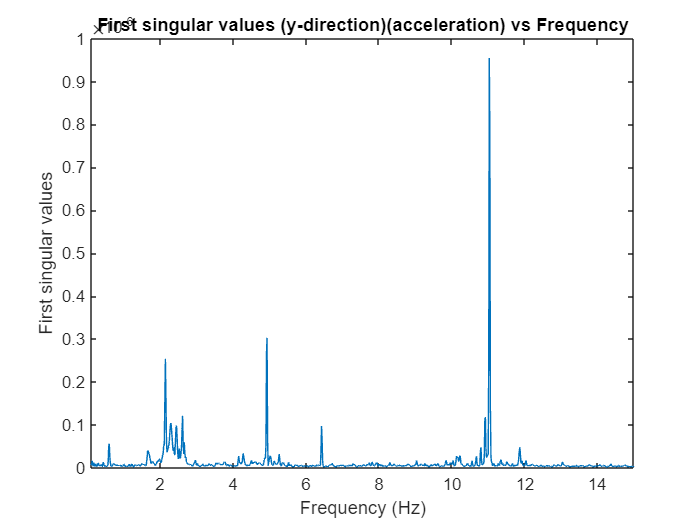

% FDD for acceleration in y-direction

T = 0.0005 ;           % Sampling period                    
fs = 1/T;

[p11,F11] = cpsd(fir_acct_y,fir_acct_y,[],[],[],fs); %fs is sampling frequency
[p12,F12] = cpsd(fir_acct_y,sec_acct_y,[],[],[],fs);
[p13,F13] = cpsd(fir_acct_y,third_acct_y,[],[],[],fs);
[p21,F21] = cpsd(sec_acct_y,fir_acct_y,[],[],[],fs);
[p22,F22] = cpsd(sec_acct_y,sec_acct_y,[],[],[],fs);
[p23,F23] = cpsd(sec_acct_y,third_acct_y,[],[],[],fs);
[p31,F31] = cpsd(third_acct_y,fir_acct_y,[],[],[],fs);
[p32,F32] = cpsd(third_acct_y,sec_acct_y,[],[],[],fs);
[p33,F33] = cpsd(third_acct_y,third_acct_y,[],[],[],fs);
f = F11';

for i = 1:length(f)
Sxx = [p11(i),p12(i),p13(i);p21(i),p22(i),p23(i);p31(i),p32(i),p33(i)];
[U,D,V] = svd(Sxx);
sigma1_y(i) = D(1,1);

U11(i)=U(1,1); % U1n for 1 st  mode, n=1
U21(i)=U(2,1);
U31(i)=U(3,1);


end
matrix_sigma1y_freq=[f' sigma1_y']; % to get indices of corresponding wn
figure;plot(f',sigma1_y');
title('First singular values (y-direction)(acceleration) vs Frequency');
xlabel('Frequency (Hz)');
ylabel('First singular values');
xlim([0.1 15]);


% Finding mode shapes using acc in y-direction data
B2=[U11; U21 ;U31];


phi1_acc_y=B2(:,141); % 3278 is the row number for wn1=2.136Hz
phi2_acc_y=B2(:,324); % 3278 is the row number for wn2=4.9285Hz
phi3_acc_y=B2(:,724); % 3278 is the row number for wn3=11.032Hz

phi_acc_y=([phi1_acc_y phi2_acc_y phi3_acc_y])

phi_acc_y =   -0.5051 + 0.0000i  -0.3341 + 0.0000i  -0.2863 - 0.0000i
   0.8615 - 0.0353i   0.7938 - 0.3063i  -0.8281 + 0.1668i
   0.0174 - 0.0348i   0.2968 - 0.2764i  -0.4417 - 0.0966i


From First singular value plots of acceleration  in x-direction, the natural frequencies are:

- wn1_acc_y=2.14 Hz

- wn2_acc__y=4.93 Hz

- wn3_acc_y=11.03Hz

The mode shapes are shown below.

% FDD for velocity in y-direction

T = t(2)-t(1);            % Sampling period                    
fs = 1/T

fs = 2000


[p11,F11] = cpsd(fir_vel_y,fir_vel_y,[],[],[],fs); %fs is sampling frequency
[p12,F12] = cpsd(fir_vel_y,sec_vel_y,[],[],[],fs);
[p13,F13] = cpsd(fir_vel_y,third_vel_y,[],[],[],fs);
[p21,F21] = cpsd(sec_vel_y,fir_vel_y,[],[],[],fs);
[p22,F22] = cpsd(sec_vel_y,sec_vel_y,[],[],[],fs);
[p23,F23] = cpsd(sec_vel_y,third_vel_y,[],[],[],fs);
[p31,F31] = cpsd(third_vel_y,fir_vel_y,[],[],[],fs);
[p32,F32] = cpsd(third_vel_y,sec_vel_y,[],[],[],fs);
[p33,F33] = cpsd(third_vel_y,third_vel_y,[],[],[],fs);
f = F11';

for i = 1:length(f)
Sxx = [p11(i),p12(i),p13(i);p21(i),p22(i),p23(i);p31(i),p32(i),p33(i)];
[U,D,V] = svd(Sxx);
sigma1_y_vel(i) = D(1,1);

U11(i)=U(1,1); % U1n for 1 st  mode, n=1
U21(i)=U(2,1);
U31(i)=U(3,1);


end
matrix_sigma1vy_freq=[f' sigma1_y_vel'] % to get indices of corresponding wn

matrix_sigma1vy_freq = 1.0e+03 *

         0    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0000    0.0000
    0.0001    0.0000
    0.0001    0.0000
    0.0001    0.0000
    0.0001    0.0000
    0.0001    0.0000
    0.0001    0.0000


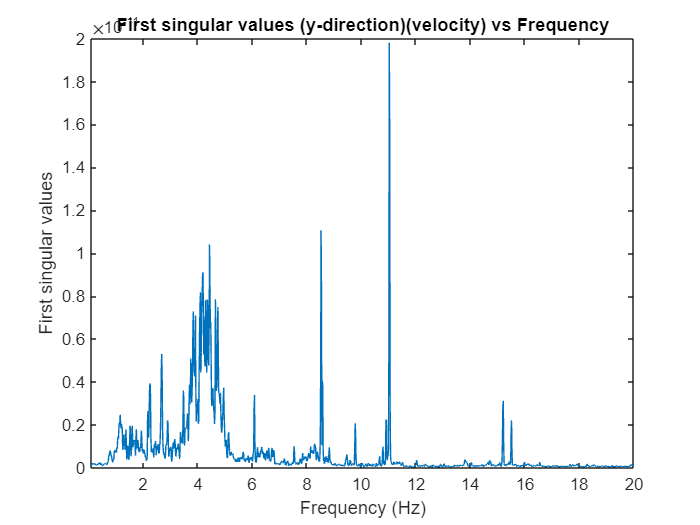

figure;plot(f',sigma1_y_vel');
title('First singular values (y-direction)(velocity) vs Frequency');
xlabel('Frequency (Hz)');
ylabel('First singular values');
xlim([0.1 20]);


% Finding mode shapes using acc in y-direction data
B12=[U11; U21 ;U31];


phi1_acc_y=B12(:,292); % 292 is the row number for wn1=4.44 Hz
phi2_acc_y=B12(:,560); % 560 is the row number for wn2=8.529Hz
phi3_acc_y=B12(:,724); % 724 is the row number for wn3=11.032Hz

phi_vel_y=([phi1_acc_y phi2_acc_y phi3_acc_y])

phi_vel_y =   -0.3660 + 0.0000i  -0.4028 + 0.0000i  -0.5945 - 0.0000i
  -0.6197 - 0.0082i  -0.6376 + 0.0352i  -0.6557 - 0.0127i
  -0.6939 - 0.0222i  -0.6552 + 0.0263i  -0.4616 - 0.0582i
